# Computational Intelligence Lab Report - Lab 12 - Mr. Amini

**Seyed Mohammadsaleh Mirzatabatabaei (9623105 - smsmt@aut.ac.ir)**

**Amirkabir University of Technology (Tehran polytechnic)**

### C-mean fuzzy theory and formulas:

#### 
$$\begin{array}{l}
\mathrm{data}:\left\lbrace x_1 ,{\;x}_2 ,{\;x}_3 ,\;\ldotp \ldotp \ldotp ,\;x_n \right\rbrace \\
n:\mathrm{Number}\;\mathrm{of}\;\mathrm{samples}
\end{array}$$


#### 
$$\begin{array}{l}
\mathrm{center}:\left\lbrace v_1 ,{\;v}_2 ,v_3 ,\;\ldotp \ldotp \ldotp ,\;v_c \right\rbrace \;\\
c:\mathrm{Number}\;\mathrm{of}\;\mathrm{clusters}
\end{array}$$
 

#### 
$$\begin{array}{l}
\mathrm{cost}\;\mathrm{function}:\;J=\sum_{k=1}^n \sum_{i=1}^c \mu_{\mathrm{ik}}^m \;\left\|\;x_{\mathrm{ik}} \;-v_i \;\right\|\;,\;m\;\epsilon \;\left\lbrack 1,\infty \right\rbrack \;,\sum_{i=1}^c \mu_{\mathrm{ik}} =1\;\;\\
\mu_{\mathrm{ik}} :\mathrm{membership}\;\mathrm{value}\;\mathrm{of}\;{\mathrm{sample}\;x}_k \;\mathrm{to}\;\mathrm{acluster}\;\mathrm{with}\;\mathrm{center}\;v_i \;-\mathrm{in}\;\mathrm{fuzzy}\;\mathrm{between}\;0\;\mathrm{and}\;1
\end{array}$$


### 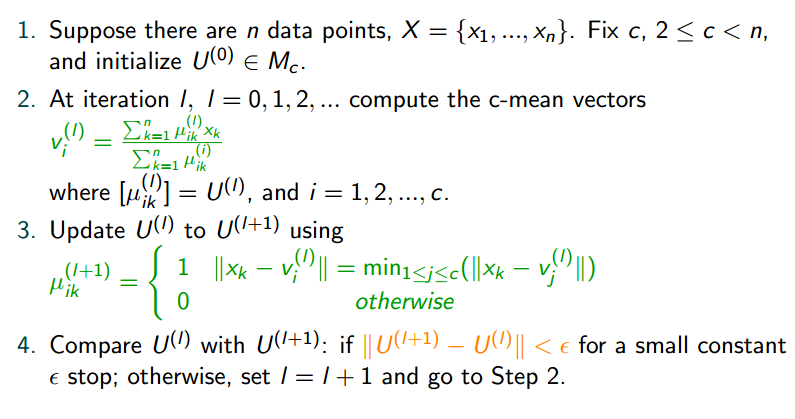

### Fuzzy C-mean algorithm in command line:

The *fcm* function performs *FCM clustering*. It starts with a random initial guess for the cluster centers; that is the mean location of each cluster. Next, `fcm` assigns every data point a random membership grade for each cluster. By iteratively updating the cluster centers and the membership grades for each data point, `fcm` moves the cluster centers to the correct location within a data set and, for each data point, finds the degree of membership in each cluster. This iteration minimizes an objective function that represents the distance from any given data point to a cluster center weighted by the membership of that data point in the cluster.

#### Clear recent data

clear; close all; clc;

#### Import data from excel file

Importing data from the following text file: Social_Network_Ads.csv

% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, 400];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "Gender", "Age", "EstimatedSalary", "Purchased"];
opts.SelectedVariableNames = ["Gender", "Age", "EstimatedSalary", "Purchased"];
opts.VariableTypes = ["string", "categorical", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Gender"], "EmptyFieldRule", "auto");

% Import the data
SocialNetworkAds = readtable("C:\Users\smsmt\Desktop\Social_Network_Ads.csv", opts);

% Clear temporary variables
clear opts;

% Social_Network_Ads table
SocialNetworkAds(1:10, :)

ans = 10×4 table
    Gender    Age    EstimatedSalary    Purchased
    ______    ___    _______________    _________

    Male      19           19000            0    
    Male      35           20000            0    
    Female    26           43000            0    
    Female    27           57000            0    
    Male      19           76000            0    
    Male      27           58000            0    
    Female    27           84000            0    
    Female    32         1.5e+05            1    
    Male      25           33000            0    
    Female    35           65000            0    


#### Fuzzy C-mean algorithm

% Convert categorical gender to number
SocialNetworkAds.Gender = double(SocialNetworkAds.Gender);
data = table2array(SocialNetworkAds);

% Calculate mean and standard deviation of data each column
std = std(data);
mean = mean(data);

% Normalize each column data with mean=0 and std=1
norm_data = normalize(data);

% Run C-mean fuzzy clustering
numberofClusters = 7;
options = [4, 1000, 1e-5, false]; % Exponent:4, Max. Iterations:100, Min. Improvement: 1e-05 
[center, U] = fcm(norm_data, numberofClusters, options);

#### Cluster centers 

convert centers to SocialNetworkAds data scale without normalize

center = center .* std + mean 

center =        1.5033       36.606        68173      0.31628
        1.465         36.3        67649      0.29746
       1.3986       44.023        86530      0.78473
       1.5689       35.839        66909      0.27553
       1.4264       43.821        85137      0.77361
       1.9354       35.705        59776     0.053191
       1.0814       34.853        62657     0.066237


#### Membership function table


$$\mu_{\mathrm{ik}} :\mathrm{value}\;\mathrm{of}\;{\mathrm{sample}\;x}_k \;\mathrm{to}\;\mathrm{acluster}\;\mathrm{with}\;\mathrm{center}\;v_i \;-\mathrm{in}\;\mathrm{fuzzy}\;\mathrm{between}\;0\;\mathrm{and}\;1$$


U

U =         0.149      0.14788      0.14788       0.1461      0.15093      0.14773      0.14945      0.14074      0.14895      0.12138      0.14926      0.14729       0.1512      0.14822      0.15082      0.15046      0.14534      0.14609      0.14558      0.14247      0.14622      0.13862      0.14353      0.14437      0.14581      0.14555       0.1444      0.14271      0.14613      0.14832      0.14635       0.1427      0.14868      0.14659      0.15216      0.14691      0.14784      0.14351      0.14819      0.14838      0.14872      0.13661      0.15193      0.14851       0.1491      0.14904      0.15139      0.14625      0.14362      0.14923
      0.14927      0.14708      0.15274      0.15182      0.15072      0.14679      0.15448      0.14066      0.14879      0.12771       0.1543      0.15259      0.15082      0.14773      0.15064      0.14864       0.1429      0.14354      0.14299      0.14252      0.14384      0.13854      0.14058      0.14462      0.14342       0.1433      0

sum(U, 1)

ans =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1


### Practices:

#### Practice 1

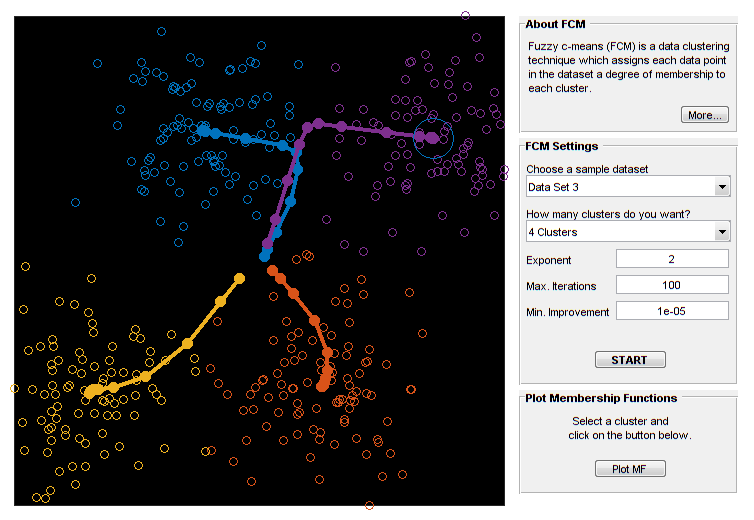

**Matlab fcm toolbox for dateset 3 with 4 cluster**

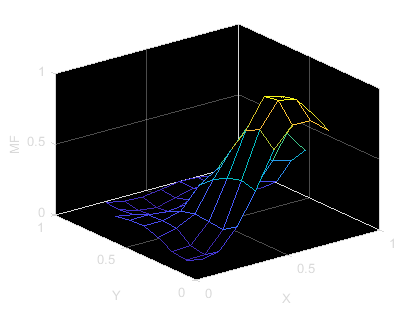

**MF plot for cluster 2 (orange)**

#### Practice 2

**Matlab fcm toolbox for dateset 5 (for 3 different times)**

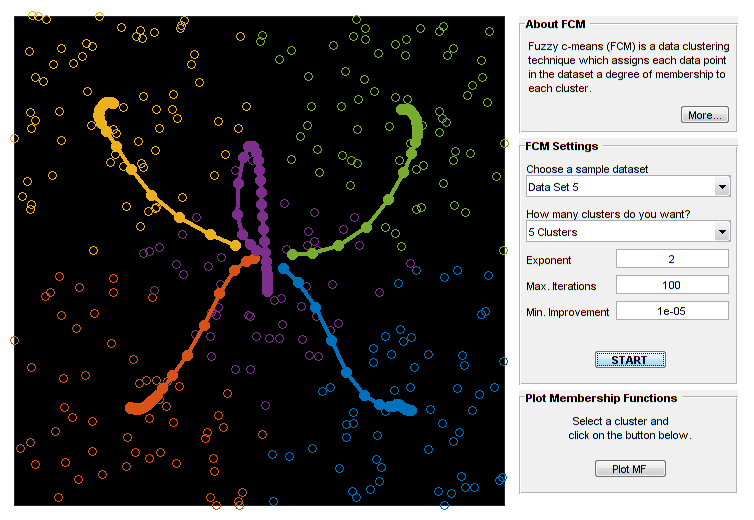

**Matlab fcm toolbox for dateset 5 with 5 cluster (number1)**

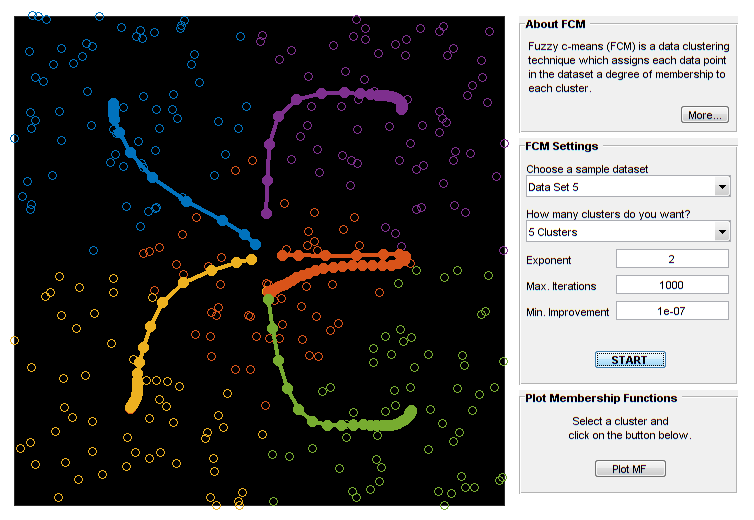

**Matlab fcm toolbox for dateset 5 with 5 cluster, 1000 Max. Iterations and 1e-07 Min. Improvement (number2)**

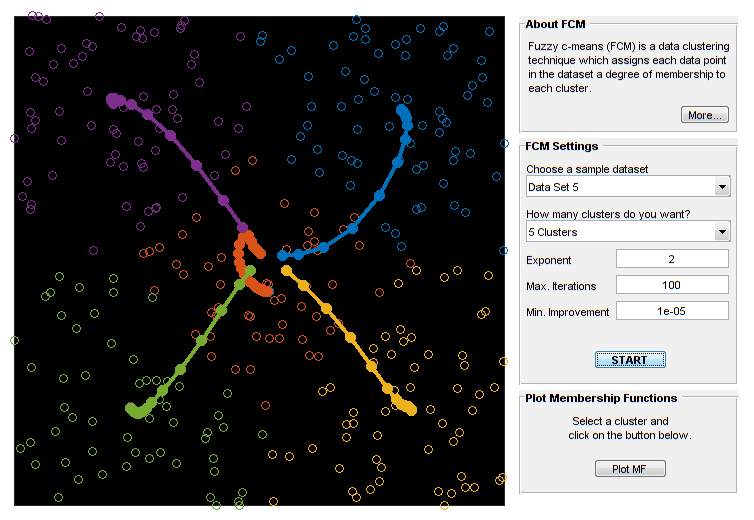

**Matlab fcm toolbox for dateset 5 with 5 cluster (number3)**

### Final comments

در ابتدای گزارش موارد مربوط به تئوری الگوریتم آورده شده است تعریف پارامتر ها فرمول ها و الگوریتم مینی مم کردن تابع هزینه نیز در این بخش آمده است

برای پیاده سازی با استفاده از بخش ایمپورت متلب اسکریپت نوشته شده و سپس ستون جنسیت به عدد تبدیل می شود در نهایت میانگین و انجراف از معیار داده های هر ستون محاسبه شده سپس داده های هر ستون با مقادیر یکسان میانگین و انحراف از معیار نرمالایز شده اند، پس از اجرای الگوریتم و پیدا شدن مراکز کلاستر ها و جدول تابع عضویت برای هر نمونه مقدار مراکز دسته ها با ضرب در انجراف معیار و سپس جمع با میانگین به مقادیر اصلی خود بازگردانی شده اند

تمرین ها نیز با استفاده از تولباکس مربوطه پیاده شده اند. در تمرین 2 برای دیتاست شماره 5 با استفاده از 5 کلاستر چندین بار فرمان شروع و اجرای الگوریتم زده شده است ، با اینکه در ابتدا خانه ها از مقادیر متفاوتی شروع به اجرای الگوریتم می کنند اما با این حال در نهایت مراکز دسته ها به مکان یکسانی به صورت دقیق همگرا می شوند که اگر چندین بار نیز ران شود مراکز به همین مقدار همگرا می شوند با عوض کردن تعداد ایتریشن ها و حداقل اختلاف برای توقف الگوریتم نیز صرفا این مقادیر دقیق تر می شوند و گرنه نقطه ی پایانی برای مراکز دسته ها در نهایت یکتا خواهند بود، همچنین داده هایی که بیشترین تعلق را به این دسته ها دارند نیز مشاهده می شود که در هر بار تکرار الگوریتم یکسان می باشند

اگر فرض کنیم الگوریتم برای داده های ما در نهایت همگرا باشد، می توان گفت به ازای فرض اولیه ی رندوم مراکز دسته ها در نهایت آنها به یک نقطه همگرا می شوند چرا که تابع هزینه در یک نقطه به مقدار کمینه خود می رسد و این نقطه کمینه همواره نشان دهنده ی مراکز دسته ها می باشد